# Demonstration of Feature Selection Functions in scGEAToolbox

## HVG analysis with single data X

cdgea; % set working directory
[X,genelist]=sc_readfile('example_data/GSM3044891_GeneExp.UMIs.10X1.txt');   

Reading example_data/GSM3044891_GeneExp.UMIs.10X1.txt ...... done.


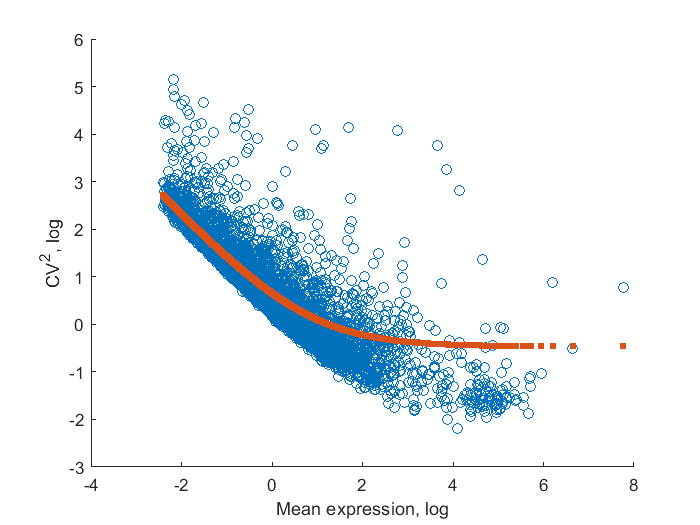

[X,genelist]=sc_selectg(X,genelist,3,1);
% Normalize data with DESeq method
Xn=sc_norm(X,'type','deseq');
[T]=sc_hvg(Xn,genelist,true,true);


% Highly variable genes (HVGenes), FDR<0.05
HVGenes=T.genes(T.fdr<0.05)

HVGenes = 814×1 string array
    "IGHG1"
    "IGHG3"
    "IGKC"
    "IGHG4"
    "IGKV1-12"
    "WFDC2"
    "CCL22"
    "IGHM"
    "CCL4"
    "CCL3L3"
    "IFI27"
    "FXYD2"
    "FXYD6-FXYD2"
    "IGLC3"
    "CCL4L2"
    "KCNMA1"
    "CKB"
    "PRKCDBP"
    "RGS1"
    "CXCL10"
    "UBD"
    "SFN"
    "CCL3"
    "NFATC1"
    "CXCL8"
    "HSPA1B"
    "IGHV1-24"
    "CCL17"
    "C10orf10"
    "PEG10"
    "RARRES2"
    "MIR3142HG"
    "HIST2H2AA3"
    "TVP23A"
    "IL32"
    "LTA"
    "BRD3"
    "SGK1"
    "CYP1B1"
    "MIR155HG"
    "IER3"
    "MAL"
    "HIST1H2BJ"
    "CCR7"
    "SOX4"
    "HIST1H2BC"
    "TNFRSF18"
    "FSCN1"
    "TUBB2B"
    "CD9"
    "HIST1H1C"
    "ATP1B1"
    "FCER1G"
    "BIN1"
    "PDLIM4"
    "IGLV6-57"
    "LTB"
    "RGS2"
    "AC092580.4"
    "TNFAIP2"
    "LMNA"
    "TNFSF4"
    "CD69"
    "TMPRSS3"
    "SSTR2"
    "NFKBIA"
    "DUSP2"
    "CD83"
    "LINC00176"
    "TUBB2A"
    "CRIP1"
    "RGS16"
    "RP5-887A10.1"
    "RSPH1"
    "JCHAIN"
    "DUSP4"
    "

## Spline-fit feature selection with single data X

[X,genelist]=sc_readfile('example_data/GSM3044891_GeneExp.UMIs.10X1.txt');   

Reading example_data/GSM3044891_GeneExp.UMIs.10X1.txt ...... done.


[X,genelist]=sc_selectg(X,genelist,3,1);

sortit=true;
[T1]=sc_splinefit(X,genelist,sortit);
% Top 50 featured genes with highest deviation (D) values 
T1.genes(1:50)

ans = 50×1 string array
    "SON"
    "IGLC2"
    "HLA-E"
    "GTPBP4"
    "CYB561A3"
    "TUBA1B"
    "AASDHPPT"
    "TAP2"
    "CHD1L"
    "SEC61B"
    "MTRNR2L8"
    "INTS1"
    "FCHO1"
    "CEBPB"
    "MRPS18C"
    "ZDHHC18"
    "TMSB4X"
    "SYNJ2BP-COX16"
    "EIF3F"
    "PHLDB3"
    "MRPS10"
    "CDC37L1"
    "PPP1CB"
    "BET1"
    "BCL2L10"
    "TMED4"
    "POLE3"
    "MTHFD2"
    "GNPNAT1"
    "DOCK8"
    "PBK"
    "GIMAP6"
    "RGS5"
    "BRK1"
    "SERF2"
    "PIM2"
    "MALAT1"
    "ARF5"
    "MSH5"
    "MRPL28"
    "RP11-708J19.1"
    "ANP32A"
    "ZNF260"
    "MBOAT2"
    "EIF3H"
    "SLC25A3"
    "SEL1L"
    "MAP2K6"
    "GLIPR1"
    "TRAPPC1"


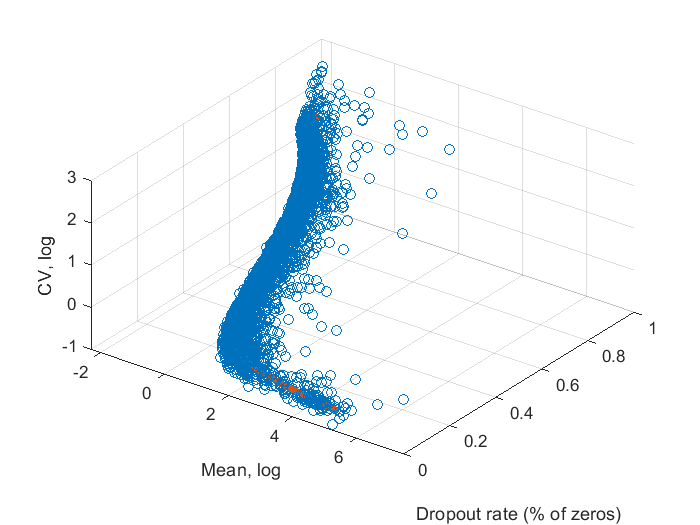

dofit=true;
showdata=true;
% Show data points and the spline-fit curve
figure;
sc_scatter3(X,genelist,dofit,showdata);
view([36.39 46.25])

## Analysis of differentially deviated (DD) genes using spline-fit feature selection with data X and Y

Read and pre-process two data sets, X and Y

[X,genelistx]=sc_readfile('example_data/GSM3204304_P_P_Expr.csv');

Reading example_data/GSM3204304_P_P_Expr.csv ...... done.


[Y,genelisty]=sc_readfile('example_data/GSM3204305_P_N_Expr.csv');

Reading example_data/GSM3204305_P_N_Expr.csv ...... done.


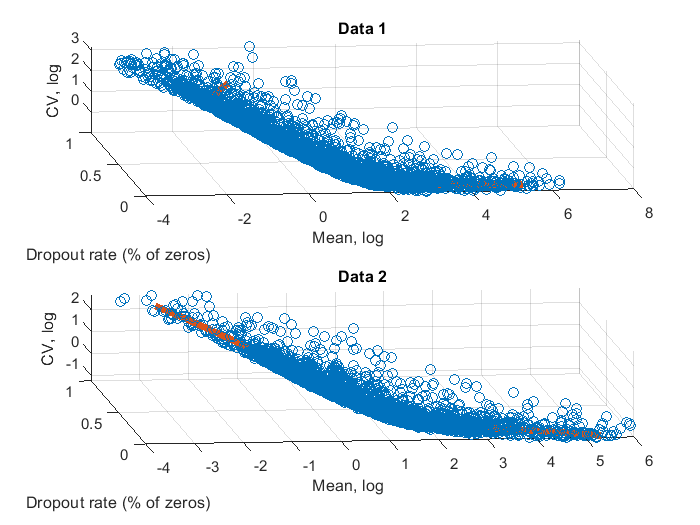

[X,genelistx]=sc_selectg(X,genelistx,3,1);
[Y,genelisty]=sc_selectg(Y,genelisty,3,1);

% Show 3D scatter plot and spline-fit curve for X
figure;
dofit=true;
showdata=true;
subplot(2,1,1)
sc_scatter3(X,genelistx,dofit,showdata);
title('Data 1')
view([-6.39 36.70])

% Show 3D scatter plot and spline-fit curve for Y
%figure;
subplot(2,1,2)
sc_scatter3(Y,genelisty,dofit,showdata);
title('Data 2')
% view([24.08 32.68])
view([-6.39 36.70])

## Using function SC_SPLINEFIT2 to fit X and Y separately and obtain DD

value for each gene.

[T2]=sc_splinefit2(X,Y,genelistx,genelisty,true);

## Top 50 genes with highest DD value.

T2.genes(1:50)

ans = 50×1 string array
    "NDUFA10"
    "ARID4A"
    "SNRPA"
    "LRRC75A"
    "IRAK1"
    "SLC7A2"
    "SDCBP2"
    "NCKAP1"
    "RPS6KB2"
    "ASCC3"
    "GNAI2"
    "NNT-AS1"
    "PIGF"
    "ZNFX1"
    "UPF3B"
    "CA9"
    "EMP2"
    "COPA"
    "CBX4"
    "EIF5A"
    "TGIF2"
    "ARF1"
    "YDJC"
    "MAPKBP1"
    "HACD1"
    "BCAS2"
    "SNAP29"
    "GJB3"
    "G6PC3"
    "MRPS5"
    "PABPC4"
    "GSTZ1"
    "APOBEC3G"
    "POLDIP3"
    "SMIM7"
    "CDC6"
    "MRPL16"
    "UNC50"
    "ARHGEF2"
    "TNRC6B"
    "MIF4GD"
    "C6orf89"
    "ZNF593"
    "ALG8"
    "ATP5G2"
    "ACP5"
    "ATP1B1"
    "CHCHD10"
    "RAB32"
    "SLC25A5"


## Run GSEAPreranked App with genes ranked with DD

addpath('thirdparty/GSEA');
a=uifig_gseapreranked;
a.load_datatable(T2);

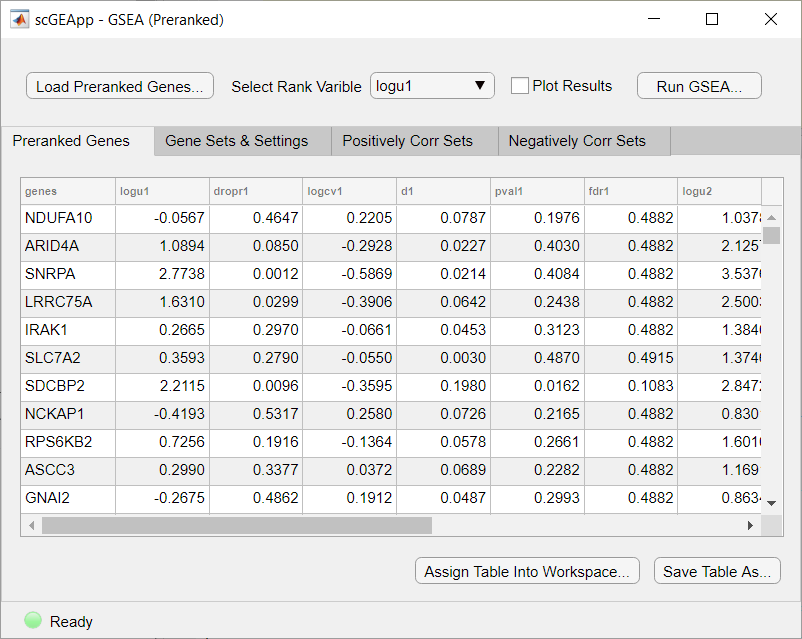

## The End